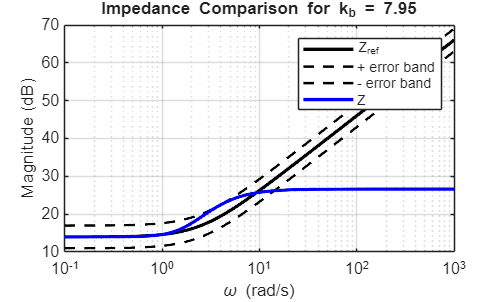

alpha = 1.2;
K = 5;
D = 2;
errBand = 3; % dB error band
zeta = 1;
dM = 0;
dgl = 0;
I = 1;

kb = 7.95;

%% Controller gains
Kp = alpha^2 - 1;
w0 = sqrt(kb * (Kp + 1) / I);
Kd = (2 * I * w0 * zeta - (dM + dgl)) / kb;

%% Coefficients
a = I + Kd * D;
b = D * (Kp + 1) + Kd * K + dM;
c = K * (Kp + 1);
d = kb * Kd + dM + dgl;
e = kb * (Kp + 1);

%% Transfer functions (use tf, not symbolic for bode)
s = tf('s');

Z = -((kb + dgl*s) * (a*s^2 + b*s + c)) / (I*s^2 + d*s + e);
Zref = K + D*s;

%% Frequency range
w = logspace(-1, 3, 1000); % rad/s

%% Get magnitude only
[magZ, ~] = bode(Z, w);
[magRef, ~] = bode(Zref, w);

% bode returns 3D arrays -> convert to vectors
magZ = squeeze(magZ);
magRef = squeeze(magRef);

%% Convert to dB
magZ_dB = 20*log10(magZ);
magRef_dB = 20*log10(magRef);

%% Error bands around Zref
upperBand = magRef_dB + errBand;
lowerBand = magRef_dB - errBand;

%% Plot
figure;
semilogx(w, magRef_dB, 'k', 'LineWidth', 2); hold on;
semilogx(w, upperBand, 'k--', 'LineWidth', 1.5);
semilogx(w, lowerBand, 'k--', 'LineWidth', 1.5);
semilogx(w, magZ_dB, 'b', 'LineWidth', 2);

grid on;
xlabel('\omega (rad/s)');
ylabel('Magnitude (dB)');
title(['Impedance Comparison for k_b = ', num2str(kb)]);
legend('Z_{ref}', '+ error band', '- error band', 'Z');

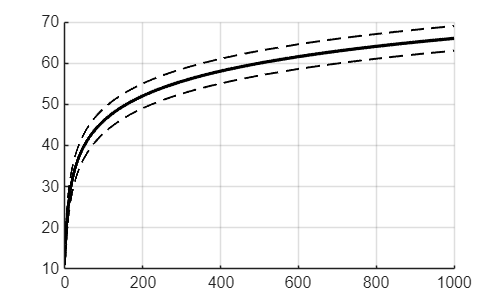

alpha = 1.2;
K = 5;
D = 2;
errBand = 3; % dB
zeta = 1;
dM = 0;
dgl = 0;
I = 1;

%% Frequency range
w = logspace(-1, 3, 2000); % rad/s

%% Reference impedance
s = tf('s');
Zref = K + D*s;

[magRef, ~] = bode(Zref, w);
magRef = squeeze(magRef);
magRef_dB = 20*log10(magRef);

upperBand = magRef_dB + errBand;
lowerBand = magRef_dB - errBand;

%% Sweep kb
kb_values = 1:0.05:20;

best_kb = NaN;
best_bw = -Inf;

bw_all = zeros(size(kb_values));

figure;
hold on;
grid on;

% Plot reference first
semilogx(w, magRef_dB, 'k', 'LineWidth', 2);
semilogx(w, upperBand, 'k--', 'LineWidth', 1.2);
semilogx(w, lowerBand, 'k--', 'LineWidth', 1.2);


for idx = 1:length(kb_values)

    kb = kb_values(idx);

    %% Gains
    Kp = alpha^2 - 1;
    w0 = sqrt(kb * (Kp + 1) / I);
    Kd = (2 * I * w0 * zeta - (dM + dgl)) / kb;

    %% Coefficients
    a = I + Kd * D;
    b = D * (Kp + 1) + Kd * K + dM;
    c = K * (Kp + 1);
    d = kb * Kd + dM + dgl;
    e = kb * (Kp + 1);

    %% Impedance function
    Z = -((kb + dgl*s) * (a*s^2 + b*s + c)) / ...
         (I*s^2 + d*s + e);

    %% Magnitude
    [magZ, ~] = bode(Z, w);
    magZ = squeeze(magZ);
    magZ_dB = 20*log10(magZ);

    %% Check where Z stays inside bounds
    inside = (magZ_dB <= upperBand) & (magZ_dB >= lowerBand);

    % Largest continuous frequency from low freq side
    last_valid_idx = find(~inside, 1, 'first');

    if isempty(last_valid_idx)
        bw = w(end); % entire range valid
    elseif last_valid_idx == 1
        bw = 0; % fails immediately
    else
        bw = w(last_valid_idx - 1);
    end

    bw_all(idx) = bw;

    %% Track best kb
    if bw > best_bw
        best_bw = bw;
        best_kb = kb;
    end

    %% Optional: plot all Z curves
    %semilogx(w, magZ_dB, 'Color', [0.7 0.7 1]);
end

%% Highlight best result
kb = best_kb;

Kp = alpha^2 - 1;
w0 = sqrt(kb * (Kp + 1) / I);
Kd = (2 * I * w0 * zeta - (dM + dgl)) / kb;

a = I + Kd * D;
b = D * (Kp + 1) + Kd * K + dM;
c = K * (Kp + 1);
d = kb * Kd + dM + dgl;
e = kb * (Kp + 1);

Z_best = -((kb + dgl*s) * (a*s^2 + b*s + c)) / ...
          (I*s^2 + d*s + e);

[magBest, ~] = bode(Z_best, w);
magBest = squeeze(magBest);
magBest_dB = 20*log10(magBest);

fprintf('\nBest k_b = %.2f\n', best_kb);


Best k_b = 7.95


fprintf('Largest valid bandwidth = %.4f rad/s\n\n', best_bw);

Largest valid bandwidth = 14.1604 rad/s



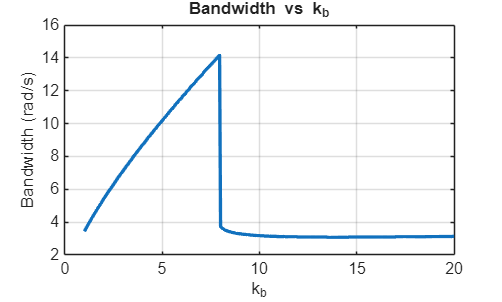


%% Optional separate plot: bandwidth vs kb
figure;
plot(kb_values, bw_all, 'LineWidth', 2);
grid on;
xlabel('k_b');
ylabel('Bandwidth (rad/s)');
title('Bandwidth vs k_b');

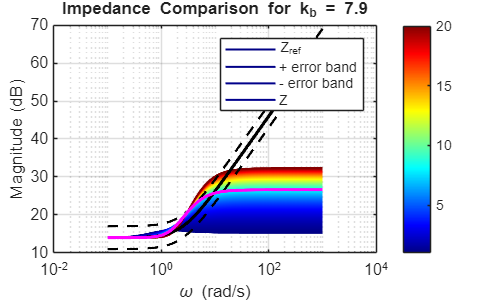

%% Optional: plot all Z curves with blue -> red color gradient

% Create colormap for all kb values
cmap = jet(length(kb_values));  
% jet goes from blue -> green -> yellow -> red

for idx = 1:length(kb_values)

    kb = kb_values(idx);

    %% Gains
    Kp = alpha^2 - 1;
    w0 = sqrt(kb * (Kp + 1) / I);
    Kd = (2 * I * w0 * zeta - (dM + dgl)) / kb;

    %% Coefficients
    a = I + Kd * D;
    b = D * (Kp + 1) + Kd * K + dM;
    c = K * (Kp + 1);
    d = kb * Kd + dM + dgl;
    e = kb * (Kp + 1);

    %% Impedance
    Z = -((kb + dgl*s) * (a*s^2 + b*s + c)) / ...
         (I*s^2 + d*s + e);

    %% Magnitude
    [magZ, ~] = bode(Z, w);
    magZ = squeeze(magZ);
    magZ_dB = 20*log10(magZ);

    %% Plot with gradient color
    semilogx(w, magZ_dB, 'Color', cmap(idx,:), 'LineWidth', 1.2);
    hold on;
end

colorbar;
colormap(cmap);
caxis([min(kb_values) max(kb_values)]);

grid on;

kb = 7.95;

%% Controller gains
Kp = alpha^2 - 1;
w0 = sqrt(kb * (Kp + 1) / I);
Kd = (2 * I * w0 * zeta - (dM + dgl)) / kb;

%% Coefficients
a = I + Kd * D;
b = D * (Kp + 1) + Kd * K + dM;
c = K * (Kp + 1);
d = kb * Kd + dM + dgl;
e = kb * (Kp + 1);

%% Transfer functions (use tf, not symbolic for bode)
s = tf('s');

Z = -((kb + dgl*s) * (a*s^2 + b*s + c)) / (I*s^2 + d*s + e);
Zref = K + D*s;

%% Frequency range
w = logspace(-1, 3, 1000); % rad/s

%% Get magnitude only
[magZ, ~] = bode(Z, w);
[magRef, ~] = bode(Zref, w);

% bode returns 3D arrays -> convert to vectors
magZ = squeeze(magZ);
magRef = squeeze(magRef);

%% Convert to dB
magZ_dB = 20*log10(magZ);
magRef_dB = 20*log10(magRef);

%% Error bands around Zref
upperBand = magRef_dB + errBand;
lowerBand = magRef_dB - errBand;

%% Plot
semilogx(w, magRef_dB, 'k', 'LineWidth', 2); hold on;
semilogx(w, upperBand, 'k--', 'LineWidth', 1.5);
semilogx(w, lowerBand, 'k--', 'LineWidth', 1.5);
semilogx(w, magZ_dB, 'm', 'LineWidth', 2);

grid on;
xlabel('\omega (rad/s)');
ylabel('Magnitude (dB)');
title(['Impedance Comparison for k_b = ', num2str(kb)]);
legend('Z_{ref}', '+ error band', '- error band', 'Z');